# Add Wind data and NNT to BS data. 

## Load data

Load Original file (without wind)

BS = [readtable('BS/birds_Sempach_2018.csv','TreatAsEmpty','NA'); readtable('BS/insects_Sempach_2018.csv','TreatAsEmpty','NA')];

Convert predicted_class ("insect" or bird) into a boolean

BS.isBird = true(size(BS,1),1); % bird
BS.isBird(strcmp(BS.predicted_class,'insect'))=false; % insect

Save as complex matrix

BS.flight = BS.groundSpeed .* exp( mod(-deg2rad(BS.direction)+90,360)*1i);

Delete unused variables

BS = removevars(BS,{'predicted_class','echoID','Var1','WFF_mea','WFF_credibility','mtr_fact','groundSpeed','direction'});

Remove data from the 2nd of January

BS(BS.time_string>datetime('2019-01-01 12:00'),:)=[];

Sort table based on date

BS = sortrows(BS,'time_string');

## Normalized Night Time

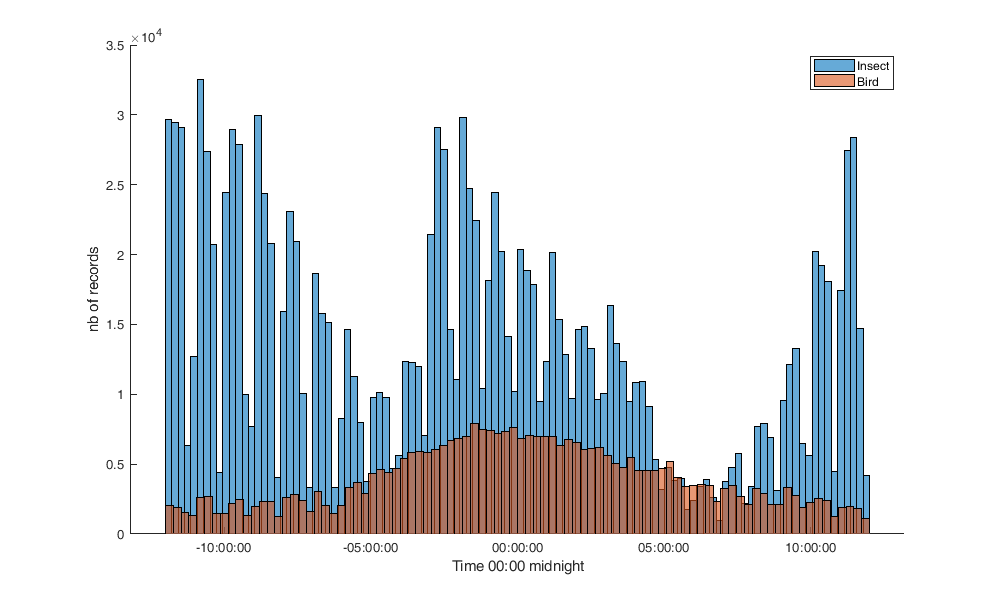

figure('position',[0 0 1000 600]); hold on;
histogram(BS.time_string(~BS.isBird)-dateshift(BS.time_string(~BS.isBird),'start','day','nearest'))
histogram(BS.time_string(BS.isBird)-dateshift(BS.time_string(BS.isBird),'start','day','nearest'))
legend({'Insect','Bird'});
xlabel('Time 00:00 midnight'); ylabel('nb of records')

Dowload data from sunrise-sunset.org

% dawn=NaT(1,numel(t));
% dusk=NaT(1,numel(t))
% for i_t=1:numel(t)
%     dd = webread(['https://api.sunrise-sunset.org/json?lat=' num2str(lat) '&lng=' num2str(lon) '&date=' datestr(t(i_t),'yyyy-mm-dd')]);
%     dawn(i_t) = datetime([datestr(t(i_t),'yyyy-mm-dd') ' ' dd.results.civil_twilight_begin]);
%     dusk(i_t) = datetime([datestr(t(i_t),'yyyy-mm-dd') ' ' dd.results.civil_twilight_end]);
%     pause(1)
% end
% dawn= dawn+1/24;
% dusk= dusk+1/24;
% save('./sunsetsunrise.mat','dawn','t','dusk');

Load the sunsetsunrise data

load('./sunsetsunrise.mat')

Compute NNT

[~,Locb] = ismember(dateshift(BS.time_string,'start', 'day','nearest'),t);
dawni = dawn(Locb)';
duski = dusk(max(Locb-1,1))';
BS.NNT = datenum(BS.time_string - mean([dawni  duski],2)) ./ datenum(dawni-duski)*2;

Figure

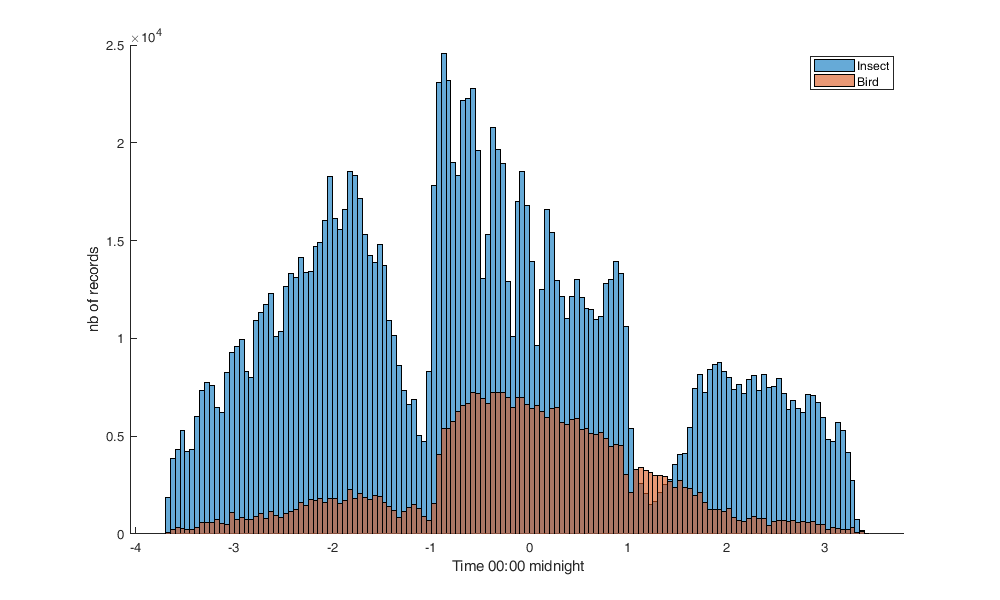

figure('position',[0 0 1000 600]); hold on;
histogram(BS.NNT(~BS.isBird))
histogram(BS.NNT(BS.isBird))
legend({'Insect','Bird'})
xlabel('Time 00:00 midnight'); ylabel('nb of records')

Remove de data

BS(BS.NNT<-1 | BS.NNT>1,:)=[];

Clear

clear dusk* dawn* Locb

## Add Wind to birdscan data

**Option 1: ERA5**

Set value of BS location.

% lat = 47.128054;
% lon = 8.192377;
% alt = 540;

RUN the interpolation from ...

% windu = Fu(repmat(lat,size(Tbs,1),1),repmat(lon,size(Tbs,1),1),datenum(Tbs.time_string), alt+Tbs.altitude);
% windv = Fv(repmat(lat,size(Tbs,1),1),repmat(lon,size(Tbs,1),1),datenum(Tbs.time_string), alt+Tbs.altitude);
% w = windu + 1i*windv;
% Tbs.windDirection = rad2deg(angle(w));
% Tbs.windSpeed = abs(w);
% uv = Tbs.groundSpeed .* exp( mod(-deg2rad(Tbs.direction)+90,360)*1i);
% a = uv-w;
% Tbs.airDirection = rad2deg(angle(a));
% Tbs.airSpeed = abs(a);

% windu = Fu(repmat(lat,size(Tis,1),1),repmat(lon,size(Tis,1),1),datenum(Tis.time_string), alt+Tis.altitude);
% windv = Fv(repmat(lat,size(Tis,1),1),repmat(lon,size(Tis,1),1),datenum(Tis.time_string), alt+Tis.altitude);
% w = windu + 1i*windv;
% Tis.windDirection = rad2deg(angle(w));
% Tis.windSpeed = abs(w);
% uv = Tis.groundSpeed .* exp( mod(-deg2rad(Tis.direction)+90,360)*1i);
% a = uv-w;
% Tis.airDirection = rad2deg(angle(a));
% Tis.airSpeed = abs(a);

**Option 2: COSMO**

Combine COSMO File (~1min)

Define grid size and variables

c.level = 50:50:3000;
c.time = datetime('2018-01-01 00:00'):1/24:datetime('2018-12-31 23:00');
id_day = datenum(dateshift(c.time,'start','day')-c.time(1))+1;
c_DD = nan(numel(c.time),numel(c.level));
c_FF = c_DD;
t= c_DD;
t2=NaT(numel(c.time),numel(c.level));

Read all file and combine into matrices

tmp=dir('cosmo\');
files = {tmp.name};
files = files(contains(files,'cosmo1'));
for i_f=1:numel(files)
    T = readtable(['cosmo\' files{i_f}],'HeaderLines',17);
    c_FF(id_day==i_f,:)=reshape(T(strcmp(T.PARAMETER,'FF'),:).P_SPA,24,numel(c.level));
    c_DD(id_day==i_f,:)=reshape(T(strcmp(T.PARAMETER,'DD'),:).P_SPA,24,numel(c.level));
    t(id_day==i_f,:)=reshape(T(strcmp(T.PARAMETER,'DD'),:).LEVEL,24,numel(c.level));
    t2(id_day==i_f,:)=reshape(T(strcmp(T.PARAMETER,'DD'),:).DATE_TIME,24,numel(c.level));
end

Save as complex matrix

c.W = c_FF .* exp( mod(-deg2rad(c_DD)+90,360)*1i);

Interpolate wind at BS measurement

F = griddedInterpolant({datenum(c.time),c.level},c.W,'pchip');
BS.wind = F(datenum(BS.time_string),BS.altitude);

Figure

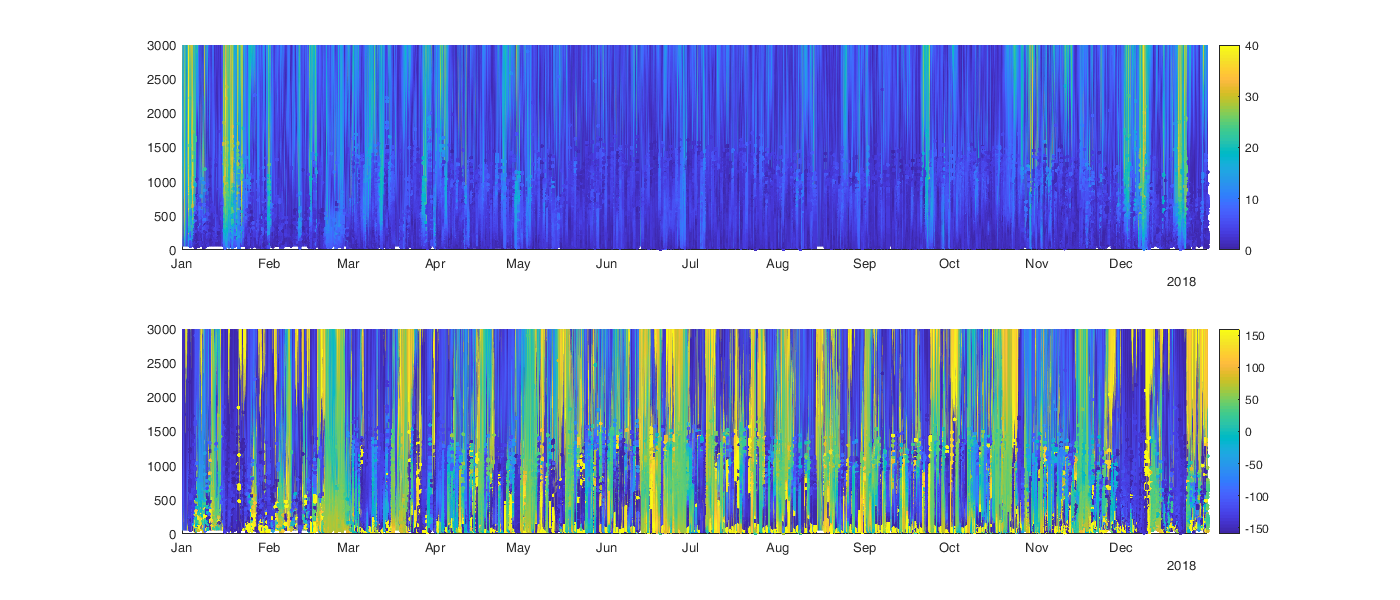

figure('position',[0 0 1400 600]); hold on;
subplot(2,1,1); hold on
surf(c.time',c.level',abs(c.W)');
shading interp;
scatter(BS.time_string,BS.altitude,[],abs(BS.wind),'.')
colorbar; caxis([0 40]); xlim([c.time(1) c.time(end)])

subplot(2,1,2); hold on;
surf(c.time',c.level',rad2deg(angle(c.W))'); shading interp;
scatter(BS.time_string,BS.altitude,[],rad2deg(angle(BS.wind)),'.')
colorbar;caxis([-160 160]); xlim([c.time(1) c.time(end)])

Write data

save('BS/Sempach_2018_combined','BS');